MEEM 4450

Vehicle Dynamics

Tire Test Rig Project

clear all
clear
clc

EXTRACT CSV DATA

% longitudinal_slip_case1=xlsread("Longitudinal Slip\Slip Data\LONG.FORCE VS LONG. SLIP(load case 1).csv",'B:B');
% longitudinal_slip_case2=xlsread("Longitudinal Slip\Slip Data\LONG.FORCE VS LONG. SLIP(load case 2).csv",'B:B');
% lateral_slip_angle_case1=xlsread("Lateral Slip\Lat Force Vs Slip Angle\LAT.FORCE VS LATERAL. SLIP(load case 1).csv",'B:B');
% lateral_slip_angle_case2=xlsread("Lateral Slip\Lat Force Vs Slip Angle\LAT.FORCE VS LATERAL. SLIP(load case 2).csv",'B:B');
% self_align_moment_case1=xlsread("Lateral Slip\Align Moment VS Slip Angle\Aligning Moment VS Slip Angle(load case 1).csv",'B:B');
% self_align_moment_case2=xlsread("Lateral Slip\Align Moment VS Slip Angle\Aligning Moment VS Slip Angle(load case 2).csv",'B:B');


Longitudinal Force VS Slip

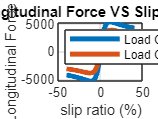

%Vertcial Load Conditions
Fv=[4635.95,3091.66];
DfDu=[1188.32,784.39].*100; %slope at slip==0
u_inf=[35.6,36]./100;
Fv_peak=[5310,3870];
u_peak=[11.4,12.3]./100;
Fv_inf=[4540,3300];
for i=1:2
    slope=DfDu(i);
    D=Fv_peak(i);
    C=1.65;
    F=Fv_inf(i);
    B=slope/(C*D);
    E=((B*u_peak(i)-tan(pi/(2*C)))./(B*u_peak(i)-atan(B*u_peak)));
    u=[-40:0.5:40]./100;
    n=length(u);
    [Fu]=magicformula(B,C,D,E(i),F,u);
    [F_long(i,1:n)]=[Fu];
end
figure (1);
plot(u*100,F_long(1,1:n),u*100,F_long(2,1:n),'LineWidth',3)
title('Longitudinal Force VS Slip Ratio (%)');
xlabel('slip ratio (%)');
ylabel('Longitudinal Force (N)');
legend('Load Case 1 = 4635.95N','Load Case 2 = 3091.66N','Location','northwest');
grid on

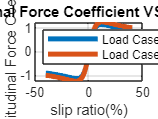


figure(2);
plot(u*100,F_long(1,1:n)/Fv(1),u*100,F_long(2,1:n)/Fv(2),'LineWidth',3)
title('Longitudinal Force Coefficient VS slip ratio(%)');
xlabel('slip ratio(%)');
ylabel('longitudinal Force Coefficient');
legend('Load Case 1 = 4635.95N','Load Case 2 = 3091.66N','Location','northwest');
grid on

Lateral Force VS Slip Angle

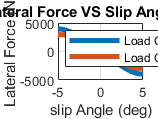

Fv=[4635.95,3091.66];
DfDu=[-1032.026,-894.776].*180/pi; %slope at slip angle ==0
u_inf=[-4.99988,-4.927].*pi/180;
Fv_peak=[3965.95,2984.09];
u_peak=[-4.99988,-4.927].*pi/180;
Fv_inf=[3965.95,2984.09];
for i=1:2
    slope=DfDu(i);
    D=Fv_peak(i);
    C=2.4;
    F=Fv_inf(i);
    B=slope/(C*D);
    E=((B*u_peak(i)-tan(pi/(2*C)))./(B*u_peak(i)-atan(B*u_peak)));
    u=[-5:0.5:5].*pi/180;
    n=length(u);
    [Fl]=magicformula(B,C,D,E(i),F,u);
    [F_lat(i,1:n)]=[Fl];
end
figure (3);
plot(u*180/pi,F_lat(1,1:n),u*180/pi,F_lat(2,1:n),'LineWidth',3)
title('Lateral Force VS Slip Angle (deg)');
xlabel('slip Angle (deg)');
ylabel('Lateral Force (N)');
legend('Load Case 1 = 4635.95N','Load Case 2 = 3091.66N','Location','northwest');
grid on

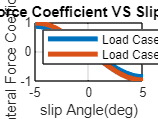


figure (4);
plot(u*180/pi,F_lat(1,1:n)/Fv(1),u*180/pi,F_lat(2,1:n)/Fv(2),'LineWidth',3)
title('Lateral Force Coefficient VS Slip Angle(deg)');
xlabel('slip Angle(deg)');
ylabel('lateral Force Coefficient');
legend('Load Case 1 = 4635.95N','Load Case 2 = 3091.66N','Location','northwest');
grid on

Self Align Moment VS Slip Angle

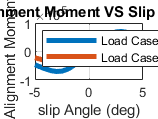

Fv=[4635.95,3091.66];
DfDu=[37617.68,23560.827].*180/pi; %slope at slip angle ==0
u_inf=[4.99998,4.99976].*pi/180;
Fv_peak=[70238.4,40627.6];
u_peak=[2.89021,2.63541].*pi/180;
Fv_inf=[44304,20479.9];
for i=1:2
    slope=DfDu(i);
    D=Fv_peak(i);
    C=2.4;
    F=Fv_inf(i);
    B=slope/(C*D);
    E=((B*u_peak(i)-tan(pi/(2*C)))./(B*u_peak(i)-atan(B*u_peak)));
    u=[-5:0.5:5].*pi/180;
    n=length(u);
    [Fsam]=magicformula(B,C,D,E(i),F,u);
    [F_sam(i,1:n)]=[Fsam];
end
figure (5);
plot(u*180/pi,F_sam(1,1:n),u*180/pi,F_sam(2,1:n),'LineWidth',3)
title('Self Alignment Moment VS Slip Angle (deg)');
xlabel('slip Angle (deg)');
ylabel('Self Alignment Moment (N-m)');
legend('Load Case 1 = 4635.95N','Load Case 2 = 3091.66N','Location','northwest');
grid on